##                                                             Robótica - Cinemática Direta

##                                                                       Lista 05 - Parte 1

clear; clc;
import RoboticaBiblioteca.*

maoDireita()

--- Regra da mão Direita ---
     eixo x --- indicador
     eixo y --- meio
     eixo z --- dedão
----------------------------
ver palma da mão -> positivo
para z: < positivo | > negativo
para x: palma da mão pra cima - positivo | palma da mão pra baixo - negativo
para y: pistola pra baixo - positivo | pistola pra cima - negativo


**Exercício 1)** Determine os parâmetros DH do robô esférico abaixo, e depois descreva o órgão terminal com relação ao sistema da origem.

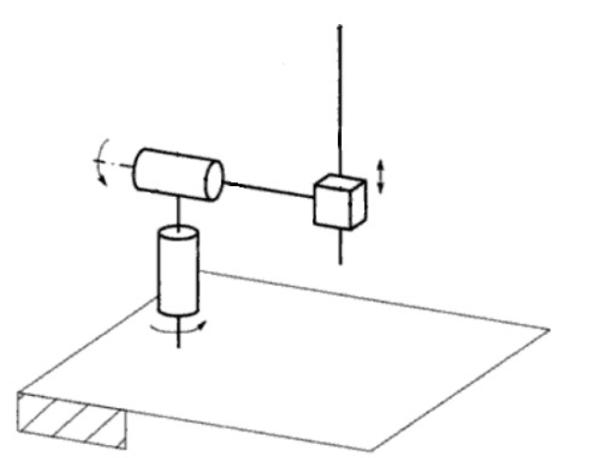

Utilize os sistemas de coordenadas do manipulador, conforme figura abaixo

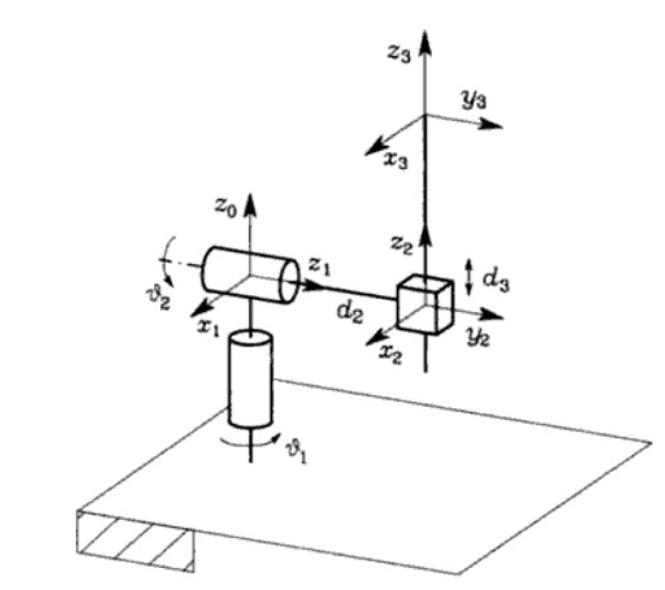

Para calcular a posição do órgão terminal, considere os seguintes valores para as variáveis das juntas:

Assumimos também que d1 = d2 = 0,4m.

Considerando que a descrição do centro do órgão terminal, com relação ao sistema 3, é:

Calcule a descrição do órgão terminal em relação a base:

|  link  |   a   | alpha |   d    |   theta   |

| 0 - 1 |   0   |   -90   |  0,4  | theta1* |  R

| 1 - 2 |   0   |  +90   |  0,4  | theta2* |  R

| 2 - 3 |   0   |     0    |  d3*  |     0      |  P

theta1 = 0;
theta2 = 90;
d3 = 0.2;
DH = [0 -90 0.4 theta1;
      0 +90 0.4 theta2 ;
      0 0 d3 0];
A03 = MatProgDenavit(DH)

A01 = 
    1.0000         0         0         0
         0         0    1.0000         0
         0   -1.0000         0    0.4000
         0         0         0    1.0000

A12 = 
         0         0    1.0000         0
    1.0000         0         0         0
         0    1.0000         0    0.4000
         0         0         0    1.0000

A23 = 
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.2000
         0         0         0    1.0000



A03 =          0         0    1.0000    0.2000
         0    1.0000         0    0.4000
   -1.0000         0         0    0.4000
         0         0         0    1.0000


p3 = [0; 0; 0; 1];
Pnovo = A03*p3

Pnovo =     0.2000
    0.4000
    0.4000
    1.0000


**Exercício 2) Validação do modelo de Denavit-Hartenberg.**

O presente texto foi retirado do artigo " MODELAGEM CINEMÁTICA DE UM ROBÔ MANIPULADOR" apresentado no COBENGE 2006.

"... O eixo referencial foi estabelecido com uma altura de 9,3cm a partir de um plano fixado como base do manipulador. O primeiro elo, a partir do eixo referencial, possui comprimento de 19,1cm, enquanto que o segundo possui 19,3cm de comprimento. O efetuador foi posicionado no punho, com um comprimento de 3,7cm. Nas Figuras 2 e 3 são demonstrados detalhes da estrutura do protótipo e na Tabela 1 são relacionados os ângulos das juntas e o comprimento dos elos...".

"...

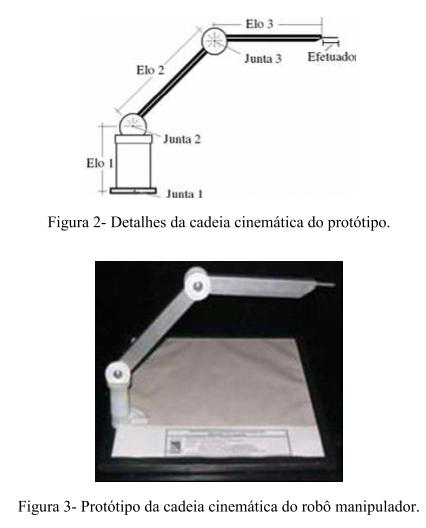

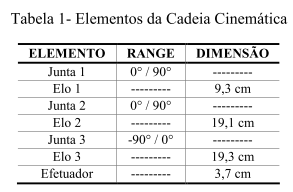

"...Como pode ser visto na Figura 3, os elos do manipulador foram constituídos por perfis de alumínio. Para a tomada das medidas dos parâmetros do manipulador e da posição final do efetuador, foi fixada uma folha de papel milimetrado na base do protótipo e uma escala em cada uma das juntas..."

Abaixo segue a cadeia cinemática com os parâmetros de Denavit-Hartenberg

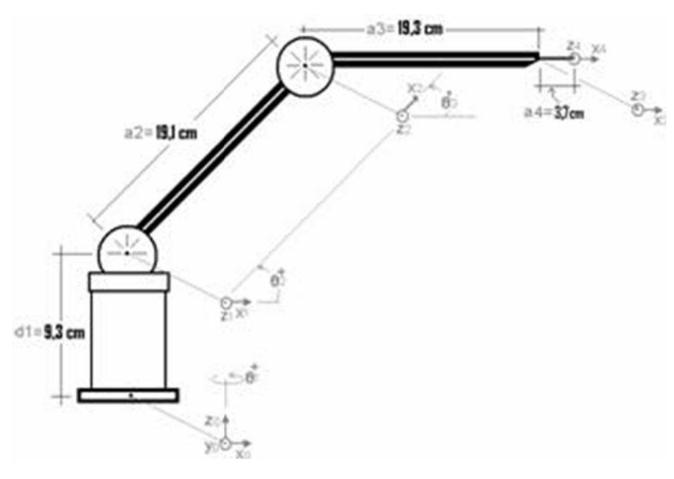

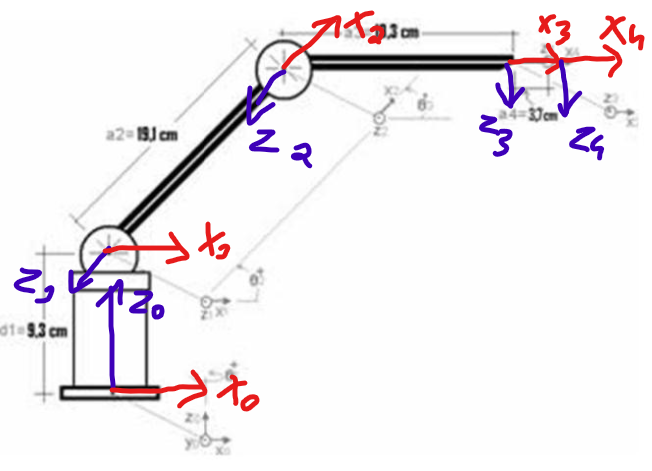

Com base no que foi dado até o momento, pede-se:

**a) **Determinação das matrizes homogêneas parciais

|  link  |    a   | alpha |   d     |   theta   |

| 0 - 1 |    0   |  +90   |  9.3   | theta1* |  R

| 1 - 2 | 19.1 |     0    |    0    | theta2* |  R

| 2 - 3 | 19.3 |     0    |    0    | theta3* |  R

| 3 - 4 |  3.7  |     0    |    0    |       0     |  

syms theta1 theta2 theta3;
DH = [0 +90 9.3 theta1;
      19.1 0 0 theta2;
      19.3 0 0 theta3;
      3.7 0 0 0];
A04 = MatProgDenavit(DH);

A01 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\cos\left(90\right)\,\sin\left(\theta_{1}\right) & \sin\left(90\right)\,\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & \cos\left(90\right)\,\cos\left(\theta_{1}\right) & -\sin\left(90\right)\,\cos\left(\theta_{1}\right) & 0\\ 0 & \sin\left(90\right) & \cos\left(90\right) & \frac{93}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & \frac{191\,\cos\left(\theta_{2}\right)}{10}\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & \frac{191\,\sin\left(\theta_{2}\right)}{10}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & \frac{193\,\cos\left(\theta_{3}\right)}{10}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & \frac{193\,\sin\left(\theta_{3}\right)}{10}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A34 = 


$$\left(\begin{array}{cccc} 1 & 0 & 0 & \frac{37}{10}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**b)** Determinação da matriz homogênea total

A04

% Compute simplified symbolic expression
simplifiedExpr = simplify(A04)

**c)** Validação do modelo encontrado para um posicionamento de 

theta1 = 45;
theta2 = 90;
theta3 = -70;
DH = [0 +90 9.3 theta1;
      19.1 0 0 theta2;
      19.3 0 0 theta3;
      3.7 0 0 0];
A04 = MatProgDenavit(DH)

A01 = 
    0.7071         0    0.7071         0
    0.7071         0   -0.7071         0
         0    1.0000         0    9.3000
         0         0         0    1.0000

A12 = 
         0   -1.0000         0         0
    1.0000         0         0   19.1000
         0         0    1.0000         0
         0         0         0    1.0000

A23 = 
    0.3420    0.9397         0    6.6010
   -0.9397    0.3420         0  -18.1361
         0         0    1.0000         0
         0         0         0    1.0000

A34 = 
    1.0000         0         0    3.7000
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000



A04 =     0.6645   -0.2418    0.7071   15.2826
    0.6645   -0.2418   -0.7071   15.2826
    0.3420    0.9397         0   36.2665
         0         0         0    1.0000


**d)** Para os valores medidos qual o erro relativo encontrado pelo método teórico os valores medidos são: X = 15,3 cm; Y = 15,3 cm e Z = 36,3 cm.

deltaX = abs(A04(1,4) - 15.3)

deltaX = 0.0174

deltaY = abs(A04(2,4) - 15.3)

deltaY = 0.0174

deltaZ = abs(A04(3,4) - 36.3)

deltaZ = 0.0335

**Exercício 3) **Robô de Stanford. A Figura abaixo apresenta o robô de Stanford de 6 graus de liberdade, sendo 5 articulações de revolução e uma prismática.

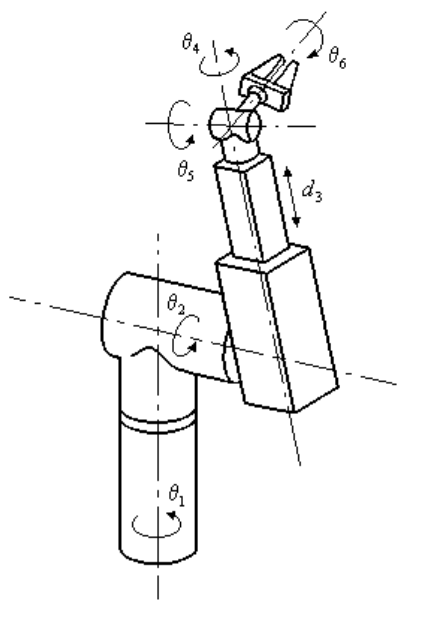

A próxima Figura apresenta um esquema deste robô com as suas articulações e com os sistemas de coordenadas posicionados nos ligamentos.

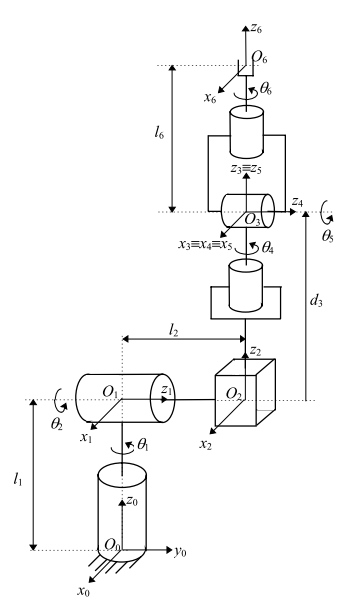

Dada a posição do manipulador apresentada acima, determine os parâmetros de D.H. bem como as matrizes de transformações homogêneas parciais e a matriz de transformação homogênea total.

|  link  |   a   | alpha |    d    |  theta      |

| 0 - 1 |   0   |   -90   |    l1   |  theta1*   |  R

| 1 - 2 |   0   |  +90   |    l2   |  theta2*   |  R

| 2 - 3 |   0   |     0    |   d3* |       0        |  P

| 3 - 4 |   0   |   -90   |    0   |   theta4*   |  R }

| 4 - 5 |   0   |  +90   |    0   |   theta5*   |  R }  Punho esférico

| 5 - 6 |   0   |     0    |    l6   |  theta6*   |  R }

syms theta1 theta2 d3 theta4 theta5 theta6;
syms l1 l2 l6;
DH = [0 -90 l1 theta1;
      0 +90 l2 theta2;
      0 0 d3 0;
      0 -90 0 theta4;
      0 +90 0 theta5;
      0 0 l6 theta6];
A06 = MatProgDenavit(DH)

A01 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\cos\left(90\right)\,\sin\left(\theta_{1}\right) & -\sin\left(90\right)\,\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & \cos\left(90\right)\,\cos\left(\theta_{1}\right) & \sin\left(90\right)\,\cos\left(\theta_{1}\right) & 0\\ 0 & -\sin\left(90\right) & \cos\left(90\right) & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\cos\left(90\right)\,\sin\left(\theta_{2}\right) & \sin\left(90\right)\,\sin\left(\theta_{2}\right) & 0\\ \sin\left(\theta_{2}\right) & \cos\left(90\right)\,\cos\left(\theta_{2}\right) & -\sin\left(90\right)\,\cos\left(\theta_{2}\right) & 0\\ 0 & \sin\left(90\right) & \cos\left(90\right) & l_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23 = 


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A34 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\cos\left(90\right)\,\sin\left(\theta_{4}\right) & -\sin\left(90\right)\,\sin\left(\theta_{4}\right) & 0\\ \sin\left(\theta_{4}\right) & \cos\left(90\right)\,\cos\left(\theta_{4}\right) & \sin\left(90\right)\,\cos\left(\theta_{4}\right) & 0\\ 0 & -\sin\left(90\right) & \cos\left(90\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A45 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & -\cos\left(90\right)\,\sin\left(\theta_{5}\right) & \sin\left(90\right)\,\sin\left(\theta_{5}\right) & 0\\ \sin\left(\theta_{5}\right) & \cos\left(90\right)\,\cos\left(\theta_{5}\right) & -\sin\left(90\right)\,\cos\left(\theta_{5}\right) & 0\\ 0 & \sin\left(90\right) & \cos\left(90\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A56 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{6}\right) & -\sin\left(\theta_{6}\right) & 0 & 0\\ \sin\left(\theta_{6}\right) & \cos\left(\theta_{6}\right) & 0 & 0\\ 0 & 0 & 1 & l_{6}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**Exercício 4) **Para o robô planar de três graus de liberdade abaixo:

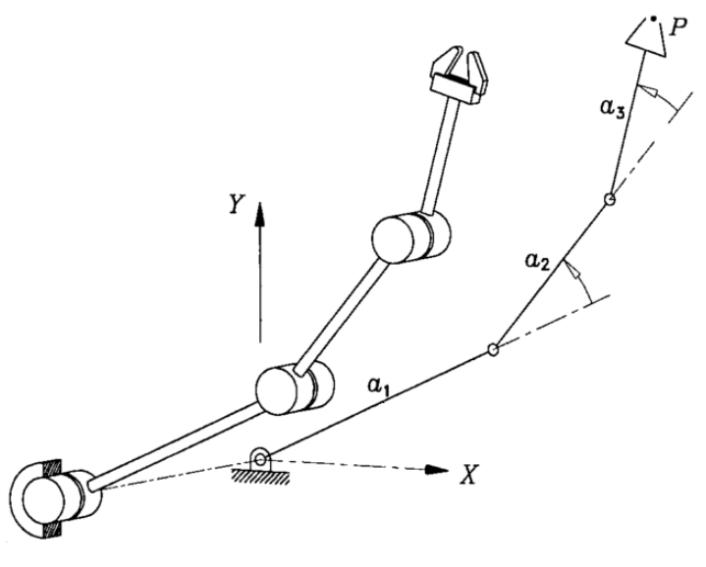

**a)** Determine os parâmetros DH;

|  link  |   a   | alpha |  d  |  theta    |

| 0 - 1 |  a1  |     0    |  0  |  theta1* |  R

| 1 - 2 |  a2  |     0    |  0  |  theta2* |  R

| 2 - 3 |  a3  |     0    |  0  |  theta3* |  R

**b) **Explique o significado de cada um dos parâmetros encontrados

Não existe angulos alfa, pois os eixos z são paralelos. Não existe distância dx porque os eixos x se inteceptam. As distâncias ax são os tamanhos dos links, pois os eixos z estão em paralelo, já os ângulos thetax são as variações dos ângulos de rotação.

**c) **Determine a posição do órgão terminal para os seguintes parâmetros:

a1 = a2 = a3 = 40cm ;

θ1= 30º

θ2 = 0º

θ3 = 45º

theta1 = 30;
theta2 = 0;
theta3 = 45;
a1 = 40;
a2 = a1;
a3 = a1;
DH = [a1 0 0 theta1;
      a2 0 0 theta2;
      a3 0 0 theta3];
A03 = MatProgDenavit(DH)

A01 = 
    0.8660   -0.5000         0   34.6410
    0.5000    0.8660         0   20.0000
         0         0    1.0000         0
         0         0         0    1.0000

A12 = 
     1     0     0    40
     0     1     0     0
     0     0     1     0
     0     0     0     1

A23 = 
    0.7071   -0.7071         0   28.2843
    0.7071    0.7071         0   28.2843
         0         0    1.0000         0
         0         0         0    1.0000



A03 =     0.2588   -0.9659         0   79.6348
    0.9659    0.2588         0   78.6370
         0         0    1.0000         0
         0         0         0    1.0000


**Exercício 5)** Um robô de pulverização especial de 3-DOF foi concebido como se segue:

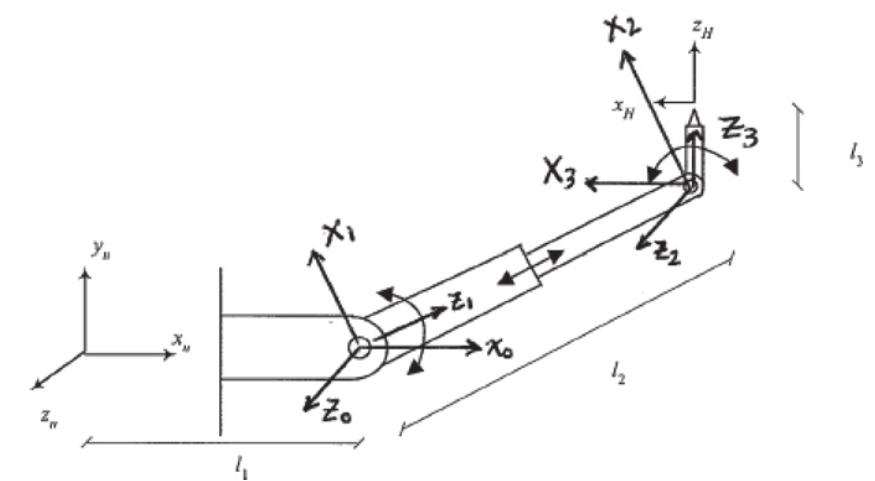

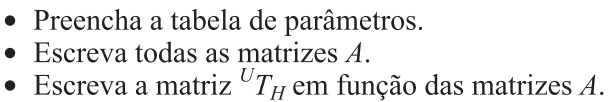

|  link  |   a   | alpha |  d  |      theta        |

| U - 0 |   l1  |     0   |   0  |          0          |  

| 0 - 1 |    0   | +90  |   0  |  theta1* + 90 |  R

| 1 - 2 |    0   |  -90  |  l2* |          0          |  P

| 2 - 3 |    0   | +90  |   0  |  theta3* + 90 |  R

| 3 - H |   0   |     0   |  l3 |          0          |  P

syms theta1 l2 theta3;
syms l1 l3;
usarDenavit()

denavit(theta, d, a, alpha)


AU0 = denavit(0, 0, l1, 0)

$$AU0 = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{1}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH = [0 +90 0 theta1+90;
      0 -90 l2 0;
      0 +90 0 theta3+90;
      0 0 l3 0];
[A0H, Alc] = MatProgDenavit(DH)

A01 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{1}+90\right) & -\sin\left(\theta_{1}+90\right)\,\cos\left(90\right) & \sin\left(\theta_{1}+90\right)\,\sin\left(90\right) & 0\\ \sin\left(\theta_{1}+90\right) & \cos\left(\theta_{1}+90\right)\,\cos\left(90\right) & -\cos\left(\theta_{1}+90\right)\,\sin\left(90\right) & 0\\ 0 & \sin\left(90\right) & \cos\left(90\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(90\right) & \sin\left(90\right) & 0\\ 0 & -\sin\left(90\right) & \cos\left(90\right) & l_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{3}+90\right) & -\sin\left(\theta_{3}+90\right)\,\cos\left(90\right) & \sin\left(\theta_{3}+90\right)\,\sin\left(90\right) & 0\\ \sin\left(\theta_{3}+90\right) & \cos\left(\theta_{3}+90\right)\,\cos\left(90\right) & -\cos\left(\theta_{3}+90\right)\,\sin\left(90\right) & 0\\ 0 & \sin\left(90\right) & \cos\left(90\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A34 = 


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$A0H = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1}+90\right)\,\cos\left(\theta_{3}+90\right)-\sin\left(\theta_{3}+90\right)\,\sigma_{5} & -\cos\left(\theta_{3}+90\right)\,\cos\left(90\right)\,\sigma_{5}-\cos\left(\theta_{1}+90\right)\,\sin\left(\theta_{3}+90\right)\,\cos\left(90\right) & \sigma_{3} & l_{3}\,\sigma_{3}+l_{2}\,\sin\left(\theta_{1}+90\right)\,\sin\left(90\right)\\ \sin\left(\theta_{3}+90\right)\,\sigma_{6}+\cos\left(\theta_{3}+90\right)\,\sin\left(\theta_{1}+90\right) & \cos\left(\theta_{3}+90\right)\,\cos\left(90\right)\,\sigma_{6}-\sin\left(\theta_{1}+90\right)\,\sin\left(\theta_{3}+90\right)\,\cos\left(90\right) & \sigma_{2}-\sigma_{4} & -l_{3}\,\left(\sigma_{4}-\sigma_{2}\right)-l_{2}\,\cos\left(\theta_{1}+90\right)\,\sin\left(90\right)\\ 0 & \sin\left(90\right)\,\sigma_{1} & \cos\left(90\right)\,\sigma_{1} & l_{2}\,\cos\left(90\right)+l_{3}\,\cos\left(90\right)\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(90\right)}^{2}+{\sin\left(90\right)}^{2}\\ \sigma_{2}=\sin\left(\theta_{1}+90\right)\,\sin\left(\theta_{3}+90\right)\,\sin\left(90\right)\\ \sigma_{3}=\cos\left(\theta_{3}+90\right)\,\sin\left(90\right)\,\sigma_{5}+\cos\left(\theta_{1}+90\right)\,\sin\left(\theta_{3}+90\right)\,\sin\left(90\right)\\ \sigma_{4}=\cos\left(\theta_{3}+90\right)\,\sin\left(90\right)\,\sigma_{6}\\ \sigma_{5}=\sin\left(\theta_{1}+90\right)\,{\cos\left(90\right)}^{2}+\sin\left(\theta_{1}+90\right)\,{\sin\left(90\right)}^{2}\\ \sigma_{6}=\cos\left(\theta_{1}+90\right)\,{\cos\left(90\right)}^{2}+\cos\left(\theta_{1}+90\right)\,{\sin\left(90\right)}^{2} \end{array}$$

Alc = 1×4 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}


AUH = AU0*A0H

$$AUH = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1}+90\right)\,\cos\left(\theta_{3}+90\right)-\sin\left(\theta_{3}+90\right)\,\sigma_{5} & -\cos\left(\theta_{3}+90\right)\,\cos\left(90\right)\,\sigma_{5}-\cos\left(\theta_{1}+90\right)\,\sin\left(\theta_{3}+90\right)\,\cos\left(90\right) & \sigma_{3} & l_{1}+l_{3}\,\sigma_{3}+l_{2}\,\sin\left(\theta_{1}+90\right)\,\sin\left(90\right)\\ \sin\left(\theta_{3}+90\right)\,\sigma_{6}+\cos\left(\theta_{3}+90\right)\,\sin\left(\theta_{1}+90\right) & \cos\left(\theta_{3}+90\right)\,\cos\left(90\right)\,\sigma_{6}-\sin\left(\theta_{1}+90\right)\,\sin\left(\theta_{3}+90\right)\,\cos\left(90\right) & \sigma_{2}-\sigma_{4} & -l_{3}\,\left(\sigma_{4}-\sigma_{2}\right)-l_{2}\,\cos\left(\theta_{1}+90\right)\,\sin\left(90\right)\\ 0 & \sin\left(90\right)\,\sigma_{1} & \cos\left(90\right)\,\sigma_{1} & l_{2}\,\cos\left(90\right)+l_{3}\,\cos\left(90\right)\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(90\right)}^{2}+{\sin\left(90\right)}^{2}\\ \sigma_{2}=\sin\left(\theta_{1}+90\right)\,\sin\left(\theta_{3}+90\right)\,\sin\left(90\right)\\ \sigma_{3}=\cos\left(\theta_{3}+90\right)\,\sin\left(90\right)\,\sigma_{5}+\cos\left(\theta_{1}+90\right)\,\sin\left(\theta_{3}+90\right)\,\sin\left(90\right)\\ \sigma_{4}=\cos\left(\theta_{3}+90\right)\,\sin\left(90\right)\,\sigma_{6}\\ \sigma_{5}=\sin\left(\theta_{1}+90\right)\,{\cos\left(90\right)}^{2}+\sin\left(\theta_{1}+90\right)\,{\sin\left(90\right)}^{2}\\ \sigma_{6}=\cos\left(\theta_{1}+90\right)\,{\cos\left(90\right)}^{2}+\cos\left(\theta_{1}+90\right)\,{\sin\left(90\right)}^{2} \end{array}$$

% Compute simplified symbolic expression
simplifiedExpr2 = simplify(AUH)

$$simplifiedExpr2 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{3}+180\right) & -\sigma_{2}-\sigma_{1} & \sigma_{4}-\sigma_{3} & l_{1}+l_{3}\,\left(\cos\left(\theta_{3}+90\right)\,\sin\left(90\right)\,\left(\sin\left(\theta_{1}+90\right)\,{\cos\left(90\right)}^{2}+\sin\left(\theta_{1}+90\right)\,{\sin\left(90\right)}^{2}\right)+\cos\left(\theta_{1}+90\right)\,\sin\left(\theta_{3}+90\right)\,\sin\left(90\right)\right)+l_{2}\,\sin\left(\theta_{1}+90\right)\,\sin\left(90\right)\\ \sin\left(\theta_{1}+\theta_{3}+180\right) & \sigma_{4}+\sigma_{3} & \sigma_{2}-\sigma_{1} & -l_{3}\,\left(\cos\left(\theta_{3}+90\right)\,\sin\left(90\right)\,\left(\cos\left(\theta_{1}+90\right)\,{\cos\left(90\right)}^{2}+\cos\left(\theta_{1}+90\right)\,{\sin\left(90\right)}^{2}\right)-\sin\left(\theta_{1}+90\right)\,\sin\left(\theta_{3}+90\right)\,\sin\left(90\right)\right)-l_{2}\,\cos\left(\theta_{1}+90\right)\,\sin\left(90\right)\\ 0 & \sin\left(90\right) & \cos\left(90\right) & \cos\left(90\right)\,\left(l_{2}+l_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(\theta_{1}+\theta_{3}+270\right)}{2}\\ \sigma_{2}=\frac{\sin\left(\theta_{1}+\theta_{3}+90\right)}{2}\\ \sigma_{3}=\frac{\cos\left(\theta_{1}+\theta_{3}+270\right)}{2}\\ \sigma_{4}=\frac{\cos\left(\theta_{1}+\theta_{3}+90\right)}{2} \end{array}$$